# Theory (Extension of supersonicShockwave.mlx):

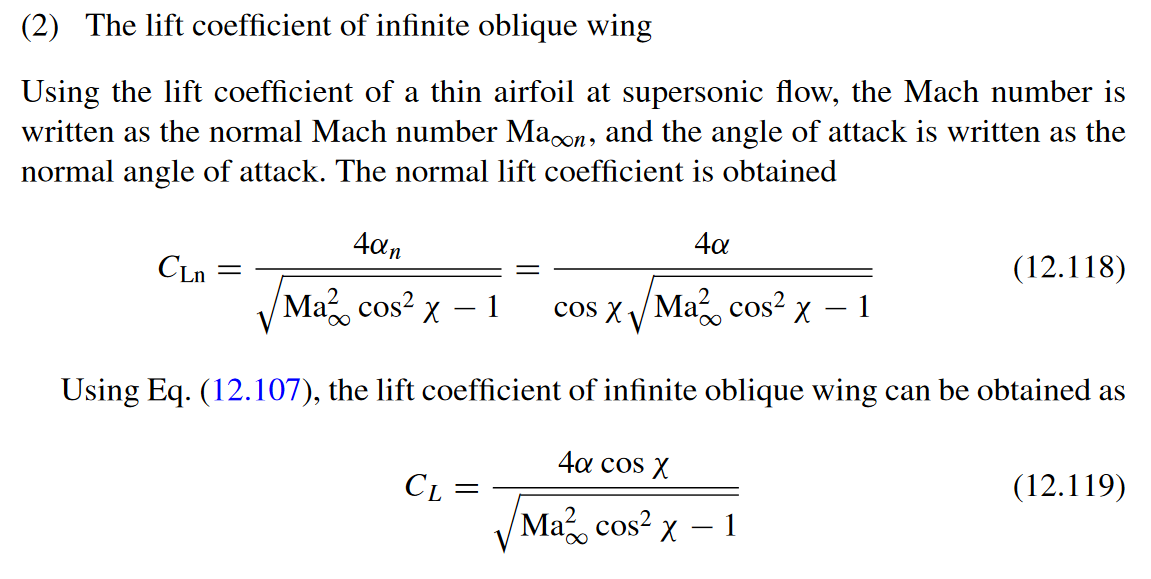

[P. Liu, Aerodynamics, https://doi.org/10.1007/978-981-19-4586-1_12]

function C_L = supersonic_sweep_lift(sweepAngle, AoA, Ma)
    disp_assumption(sprintf('supersonic_sweep_lift() assumes: \n\t - attached supersonic flow (low AoA, Ma) \n\t - thin flat plate airfoil \n\t - infinite wing span \n'));

    if AoA > 7
        disp_warning("Warning: Angle of Attack (AoA) is more than 7°, Linear Lift Theory assumes attached flow and low AoA", "supersonic_sweep_lift()");
    end

    if Ma > 2
        disp_warning("Warning: Mach Number (Ma) is above 2, Linear Lift Theory assumes supersonic attached flow. (for hypersonic flow use 'Newtonian Impact Theory')", "supersonic_sweep_lift()");
    end

    C_L = 4*deg2rad(AoA)*cosd(sweepAngle)/sqrt(Ma^2*cosd(sweepAngle)^2-1);


# Comment:

Roughly aligns with [E. Arthur Bonney - Engineering Supersonic Aerodynamics]. He proposes no direct equation for the lift coefficient but rather the nromal force:

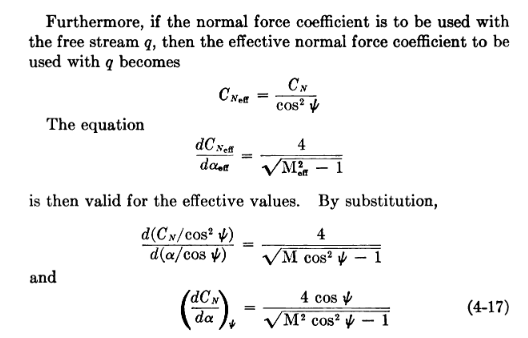

with